## Task 1

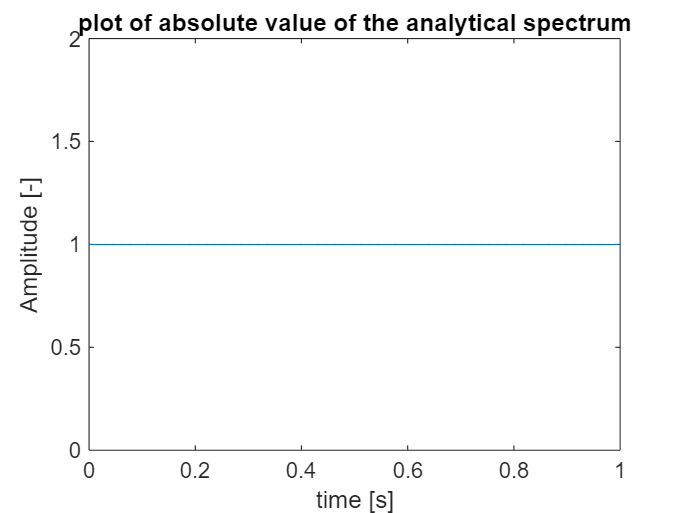

%Ex. 1.1
clear
%creating the signal
N = 1000;
fs = 1000;
t = (0:N-1)/fs; % time range
f1 = 30;
a1 = 1;
df = fs / N;
fv = (0:N-1) * df;

%creating signal
y = a1*sin(2*pi*f1*t);
%calculating hilbert transform of the sine wave
yh = hilbert(y);
YH = fft(yh);
%plotting absolute value of the spectrum
figure()
plot(t,abs(yh))
xlabel('time [s]')
ylabel('Amplitude [-]')
title('plot of absolute value of the analytical spectrum')
ylim([0 2])

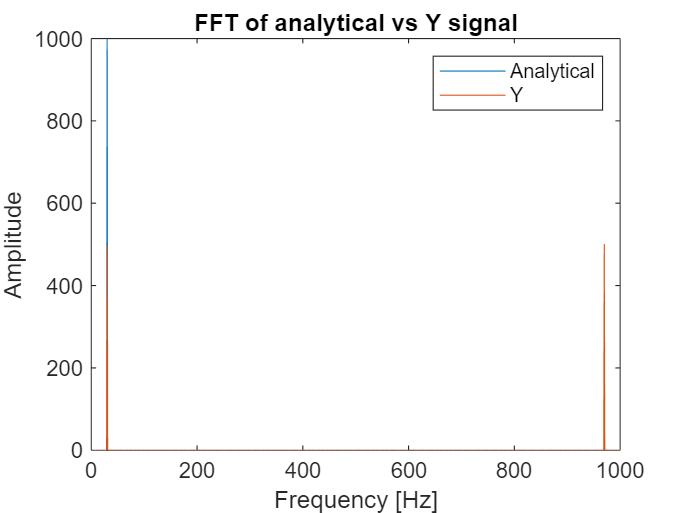

%plotting FFT of signal
figure()
plot(fv, abs(YH)),hold on;
plot(fv,abs(fft(y))),hold off;
legend('Analytical','Y')
title('FFT of analytical vs Y signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

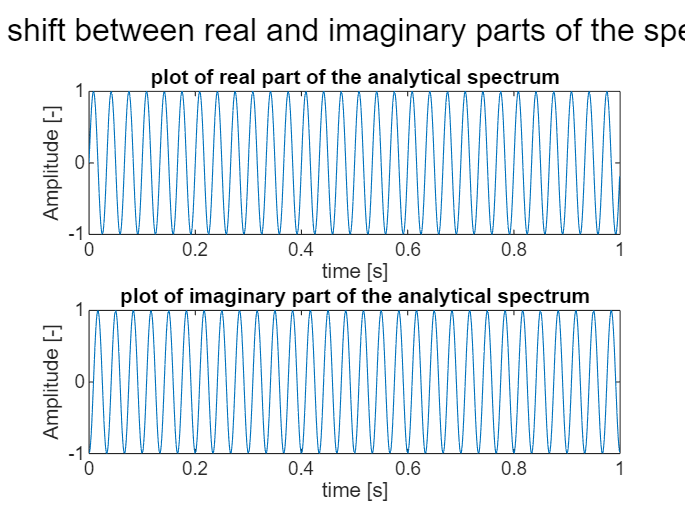


%comparing real vs imaginary part of the analytical spectrum
figure()
subplot(2,1,1)
plot(t,real(yh))
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of real part of the analytical spectrum')
subplot(2,1,2)
plot(t,imag(yh))
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of imaginary part of the analytical spectrum')
sgtitle('phase shift between real and imaginary parts of the spectrum')

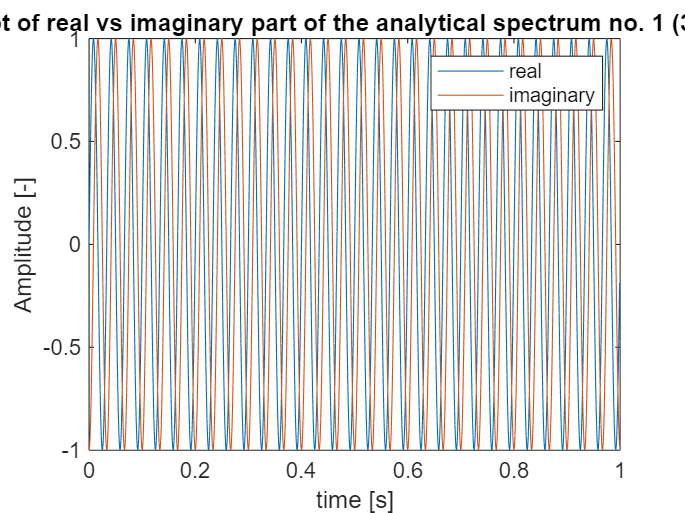

%checking phase shift
figure()
plot(t,real(yh)), hold on
plot(t,imag(yh)), hold off
legend('real','imaginary')
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of real vs imaginary part of the analytical spectrum no. 1 (30Hz)')

%calculating time shift
dt=0.016-0.008; %[s]
T=1/f1;
dphi1 = 360*dt/T 

dphi1 = 86.4000

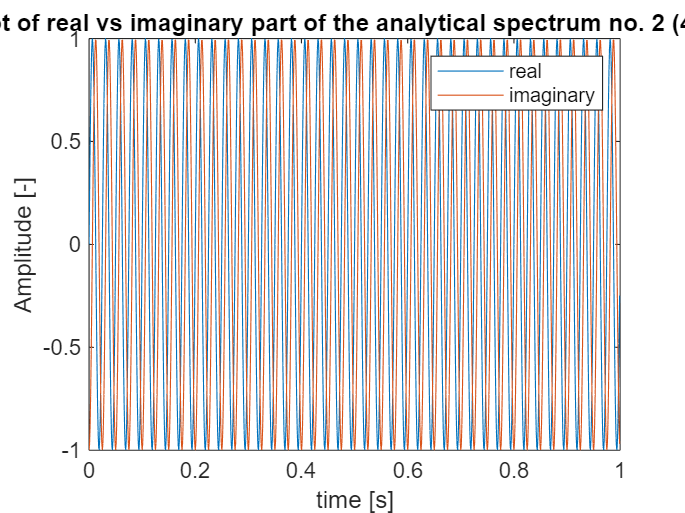

%recalculating phase shift for a different frequency
f2 = 40;
y2 = a1*sin(2*pi*f2*t);
%calculating hilbert transform of the sine wave
yh2 = hilbert(y2);
%plotting absolute value of the spectrum
%checking phase shift
figure()
plot(t,real(yh2)), hold on
plot(t,imag(yh2)), hold off
legend('real','imaginary')
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of real vs imaginary part of the analytical spectrum no. 2 (40Hz)')

%calculating time shift
dt2=0.012-0.006; %[s]
T2=1/f2;
dphi2 = 360*dt2/T2 

dphi2 = 86.4000

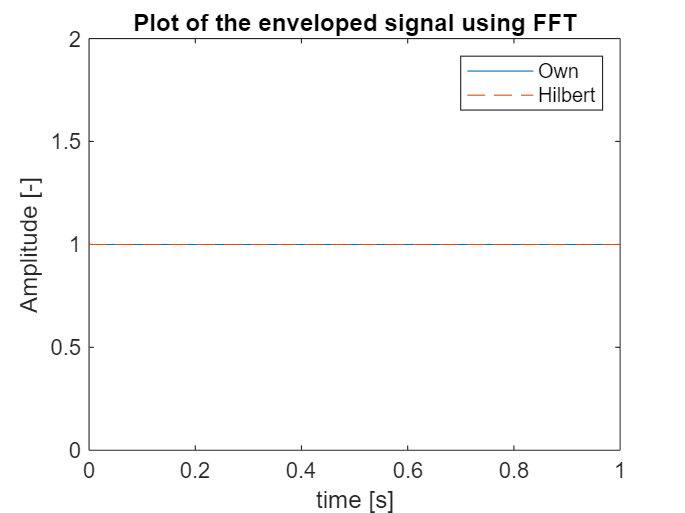

%% task 1.2
% Calculating the envelope using Fourier Transform
Y_fft = fft(y); % Compute FFT of the signal
idx = find((1:length(Y_fft)) > 500);
Y_fft(idx) = 0;
y_nH = ifft(Y_fft);
y_nH = 2 * y_nH;
Y_NH = fft(y_nH);
figure()
plot(t,abs(y_nH)),hold on
plot(t,abs(yh),'--'),hold off
xlabel('time [s]')
ylabel('Amplitude [-]')
title('Plot of the enveloped signal using FFT')
legend('Own','Hilbert')
ylim([0 2])

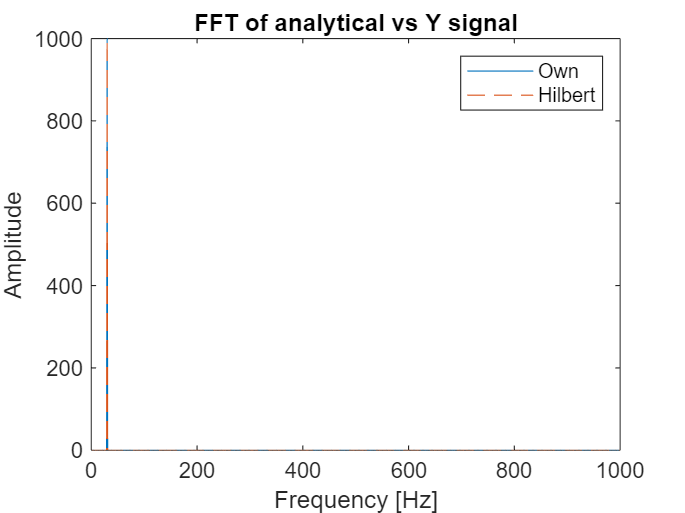

%plotting FFT of signal
figure()
plot(fv,abs(Y_NH) ),hold on;
plot(fv,abs(YH),'--'),hold off;
legend('Own','Hilbert')
title('FFT of analytical vs Y signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

## Task2.1

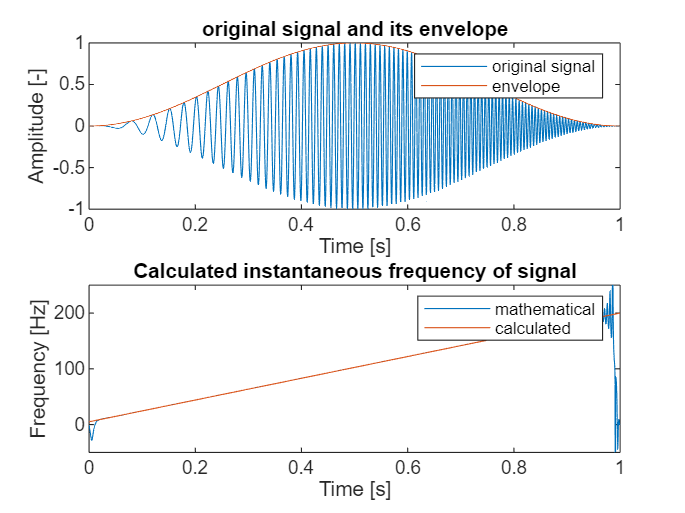

clear
N = 2000; %2000 samples
Fs = 2000; %sampling frequency
T = (0:N-1)/Fs; % time range
F0 = 5; %Hz
F1 = 200; %Hz
T1 = 1;
Y = chirp(T,F0,T1,F1, 'linear' );
h = hann(N);
y = Y.*h';%computing analytical spectrum
yh = hilbert(y);
%computing phase of the signal
phase = angle(yh);
%unwrapping phase
phase_unwrap = unwrap(phase);
%calculating the derivative
dphase = diff(phase_unwrap);
%scaling the derivative to get instantenuous frequency
inst_freq = dphase*Fs/(2*pi);
%plotting the results
figure()
subplot(2,1,1)
plot(T, y), hold on
plot(T, abs(yh)), hold off
xlabel('Time [s]')
ylabel('Amplitude [-]')
legend('original signal','envelope')
title('original signal and its envelope')
subplot(2,1,2)
plot(T(1:(length(T)-1)),inst_freq), hold on
f = @(x) 195*x+5;
fplot( f,[0,1])
xlabel('Time [s]')
ylabel('Frequency [Hz]')
title('Calculated instantaneous frequency of signal')
legend('mathematical','calculated')
ylim([-50 250])

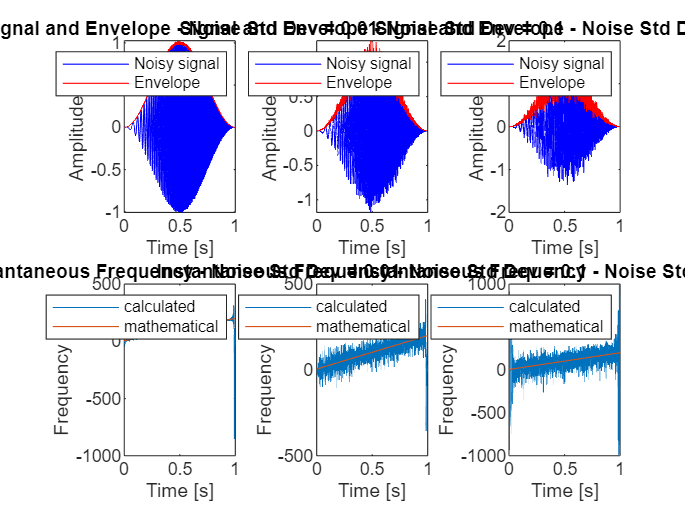

%% Task 2.2
noise1 = 0.01 * randn(N, 1)';
noise2 = 0.1 * randn(N, 1)';
noise3 = 0.2 * randn(N, 1)';
% Add noise to the signal
Y_noise1 = Y + noise1;
Y_noise2 = Y + noise2;
Y_noise3 = Y + noise3;
y1 = Y_noise1 .* h';
y2 = Y_noise2 .* h';
y3 = Y_noise3 .* h';
noisy_signals = {y1, y2, y3};
titles = {'Noise Std Dev = 0.01', 'Noise Std Dev = 0.1', 'Noise Std Dev= 0.2'};
figure;
for i = 1:3
    y_current = noisy_signals{i};
    yh = hilbert(y_current);
    envelope = abs(yh);
    phase = angle(yh);
    phase_unwrap = unwrap(phase);
    dphase = diff(phase_unwrap);
    inst_freq = dphase * Fs / (2 * pi);
    subplot(2, 3, i);
    plot(T, y_current, 'b', T, envelope, 'r');
    xlabel('Time [s]');
    ylabel('Amplitude [-]');
    legend('Noisy signal', 'Envelope');
    title(['Signal and Envelope - ', titles{i}]);
    subplot(2, 3, i+3);
    plot(T(1:end-1), inst_freq),hold on;
    fplot( f,[0,1])
    xlabel('Time [s]');
    ylabel('Frequency [Hz]');
    title(['Instantaneous Frequency - ', titles{i}]);
    legend('calculated', 'mathematical');
end

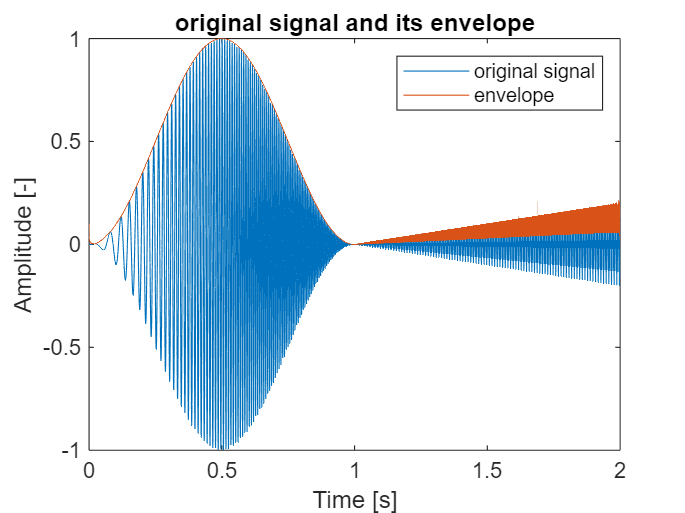

%% task2.3
y_sin = 0.1*T.*sin(2*pi*T*100) + 0.1*T.*sin(2*pi*T*500);
y2 = zeros(1,4000);
y2(1:2000)=y;
y2(2001:4000)=y_sin;
%computing analytical spectrum
yh = hilbert(y2);
%computing phase of the signal
phase = angle(yh);
%unwrapping phase
phase_unwrap = unwrap(phase);
%calculating the derivative
dphase = diff(phase_unwrap);
%scaling the derivative to get instantenuous frequency
inst_freq = dphase*Fs/(2*pi);
%plotting the results
figure()
plot((0:2*N-1)/Fs,y2), hold on
plot((0:2*N-1)/Fs,abs(yh)), hold on
xlabel('Time [s]')
ylabel('Amplitude [-]')
legend('original signal','envelope')
title('original signal and its envelope')

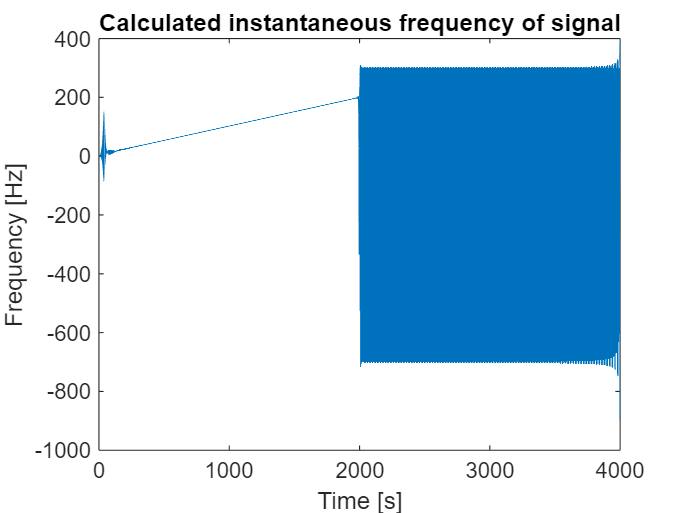

figure()
plot(inst_freq)
xlabel('Time [s]')
ylabel('Frequency [Hz]')
title('Calculated instantaneous frequency of signal')

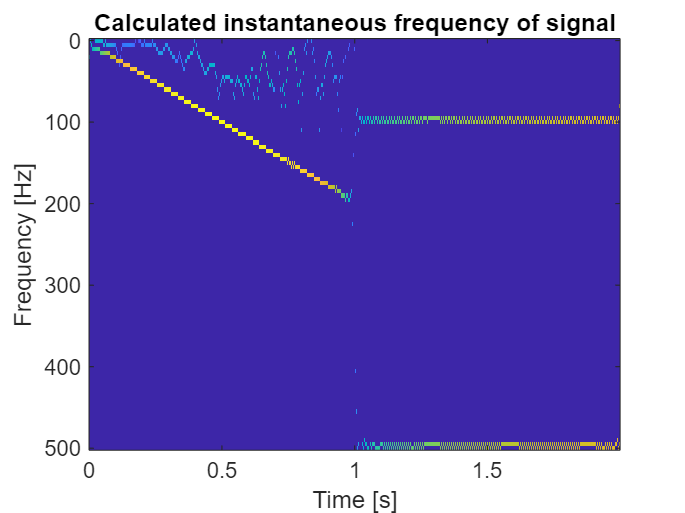

[imf,residual] = emd(y2);
[dat,freq,time] = hht(imf,Fs, 'FrequencyLimits' ,[0 500]);
figure()
imagesc(time,freq,log(dat))
xlabel('Time [s]')
ylabel('Frequency [Hz]')
title('Calculated instantaneous frequency of signal')

## 3

clear
N = 2000; %2000 samples
Fs = 2000; %converting 2kHz into Hz
T = (0:N-1)/Fs; % time range
F0 = 5; %Hz
F1 = 200; %Hz
T1 = 1;
Y = chirp(T,F0,T1,F1, 'linear' );
h = hann(N);
y = Y.*h';
%computing analytical spectrum
yh = hilbert(y);
%creating the second Chirp
phi = -60; % Phase shift in degrees
Y2 = chirp(T, F0, 1, F1, 'linear', phi);
y2 = Y2.*h';
%Using the analytical signal to apply the phase shift:
ya = hilbert(y); % Analytical signal
phi_rad = deg2rad(phi); % Phase shift in radians
y2_analytic = real(ya .* exp(1i * phi_rad));
%Calculate the phase shift between y and y2:
y2a = hilbert(y2_analytic); % Analytical signal of y2
delta_phi = -angle(sum(ya .* conj(y2a)) / sum(abs(y2a).^2));
delta_phi_deg = rad2deg(delta_phi); % Convert to degrees
disp(['Calculated phase shift: ', num2str(delta_phi_deg), ' degrees']);

Calculated phase shift: -60 degrees


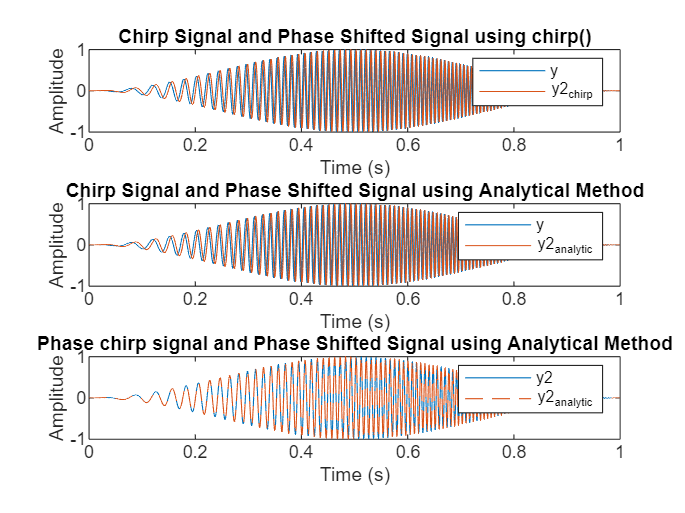

%Plot the signals and compare:
figure;
subplot(3,1,1);
plot(T, y); hold on;
plot(T, y2); hold off;
title('Chirp Signal and Phase Shifted Signal using chirp()');
legend('y', 'y2_{chirp}');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,2);
plot(T, y); hold on;
plot(T, y2_analytic); hold off;
title('Chirp Signal and Phase Shifted Signal using Analytical Method');
legend('y', 'y2_{analytic}');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,3);
plot(T, y2); hold on;
plot(T, y2_analytic,'--'); hold off;
title('Phase chirp signal and Phase Shifted Signal using Analytical Method');
legend('y2', 'y2_{analytic}');
xlabel('Time (s)');
ylabel('Amplitude');

%% task. 3.2
%Creating a time-varying phase-shifted signal (y3):
phase_shift = -2 * pi * T; % Time-varying phase shift
y3 = real(ya .* exp(1i * phase_shift));
%Calculate the average phase shift between y and y3
y3a = hilbert(y3); % Analytical signal of y3
avg_phase_shift = -angle(sum(ya .* conj(y3a)) / sum(abs(y3a).^2));
avg_phase_shift_deg = rad2deg(avg_phase_shift); % Convert to degrees
disp(['Average phase shift: ', num2str(avg_phase_shift_deg), 'degrees']);

Average phase shift: -179.91degrees


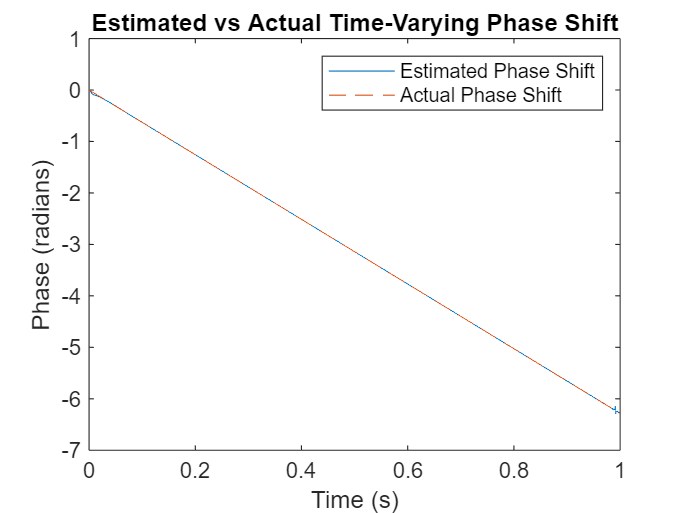

%Estimate the time-varying phase shift
time_varying_phase_shift = -angle(ya .* conj(y3a));
time_varying_phase_shift_unwrapped = unwrap(time_varying_phase_shift);
figure;
plot(T, time_varying_phase_shift_unwrapped), hold on;
plot(T, phase_shift, '--'), hold off;
title('Estimated vs Actual Time-Varying Phase Shift');
legend('Estimated Phase Shift', 'Actual Phase Shift');
xlabel('Time (s)');
ylabel('Phase (radians)');
hold off;

%% 

## task4

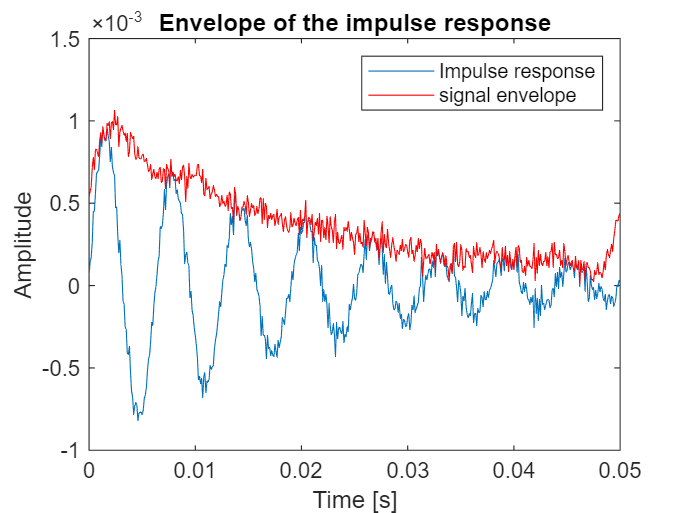

% Model coefficients
m1 = 1;
c1 = 100;
k1 = 1e6;
damping_coefficient = c1 / (2 * sqrt(k1 * m1));
% Natural frequency of the system
fc = sqrt(k1 / m1) / (2 * pi);
% Transmittance of the system
sys = tf(1, [m1 c1 k1]);
fs = 1e4;
t = 0:1/fs:0.05;
s = length(t);
% Impulse response of the signal
y = impulse(sys, t);
y = y + 5e-5 * randn(s, 1);
%% 1. CALCULATE THE ENVELOPE OF THE Y SIGNAL
analytic_signal = hilbert(y);
up = abs(analytic_signal);
figure()
plot(t, y),hold on;
plot(t, up, '-r')
title('Envelope of the impulse response')
xlabel('Time [s]')
ylabel('Amplitude')
legend('Impulse response', 'signal envelope')

%% 2. CALCULATE THE LOGARITHM OF THE ENVELOPE, SCALE IN DB
log_env = 20 * log10(up);
% Fit a polynomial (e.g. order 4) to the estimated envelope
p = polyfit(t, log_env, 4);
EnvFit = polyval(p, t);
%% 3. READ THE TIME CONSTANT FROM EnvFit GRAPH (based on -8.7 dBamplitude change)
tau=0.0215;
%% 4. CALCULATE THE DAMPING FACTOR FROM THE TIME CONSTANT
omega_n = 2 * pi * fc;
damping_factor = 1 / (tau * omega_n);
% Display results
disp(['Calculated damping factor: ', num2str(damping_factor)]);

Calculated damping factor: 0.046512


disp(['Theoretical damping factor: ', num2str(damping_coefficient)]);

Theoretical damping factor: 0.05


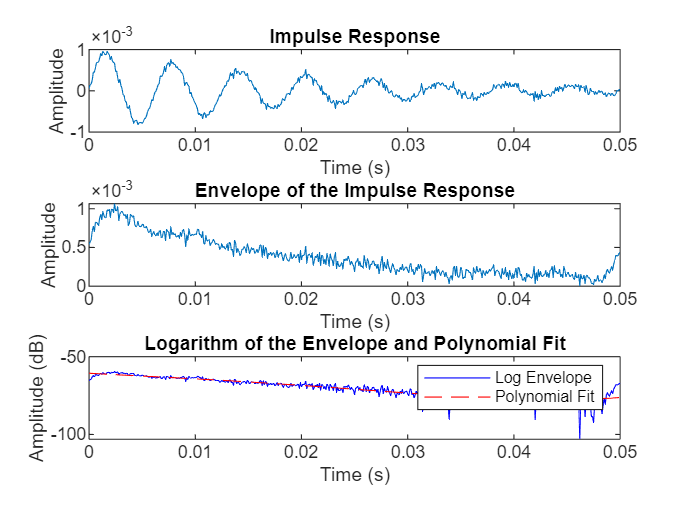

%% Plot graphs
figure;
subplot(3,1,1);
plot(t, y);
title('Impulse Response');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,2);
plot(t, up);
title('Envelope of the Impulse Response');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,3);
plot(t, log_env, 'b', t, EnvFit, 'r--');
title('Logarithm of the Envelope and Polynomial Fit');
xlabel('Time (s)');
ylabel('Amplitude (dB)');
legend('Log Envelope', 'Polynomial Fit');